# A PI Consensus Controller for Networked Clocks Synchronization

## Design of the PI Consensus Controller

The closed-loop system dynamics is:

The corresponding system in matrix form is:


$$\left\lbrack \begin{array}{c}
x\left(k+1\right)\\
w\left(k+1\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
I-L & -I\\
\gamma L & I
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\left(k\right)\\
w\left(k\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
d\\
0
\end{array}\right\rbrack$$


In the following simulation, we will focus on the effectiveness (convergence) of this controller, and design of $\gamma$ to accelerate the  convergence. More analysis please refer to our project report and the reference papers.

## Generate an Undirected Weighted Graph

In this part, we keep the same setting with the original paper:

"In this simulation we consider a connected random geometric graph generated by choosing N = 15 points uniformly distributed in the unit square, and then placing an edge between each pair of points at distance less than 0.3.  "

“The speeds of the clocks and the initial local time has been chosen randomly respectively inside the interval [0.5, 1.5] and the interval [0, 200]. ”

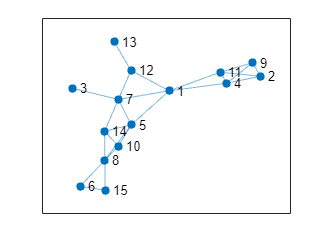

clear;clc;
N=15;

rand('seed', 22);   % strongly connected seed options: 14, 22, 24
xlist=rand([N,1]);
ylist=rand([N,1]);

Ad=zeros(N,N);
for i=1:N

    Neighbor_num_i=0;
    for j=1:N
        d=sqrt( (xlist(i)-xlist(j))^2 + (ylist(i)-ylist(j))^2);
        if d<0.3
            Ad(i,j)=rand([1,1]);
            Neighbor_num_i=Neighbor_num_i+1;
        end
    end
    Ad(i,i)=0;
    Adw(i,:)=0.9* Ad(i,:)/sum(Ad(i,:));  
end
Adw_sym=(Adw+Adw')/2;
%clock speed
d=0.5+rand([N,1]);

%initial local time
x0list=200*rand(N,1);
G=graph(Adw_sym);
plot(G)


%Laplacian matrix
degree=diag(Adw_sym*ones(N,1));
L=degree-Adw_sym;


## Control Simulation

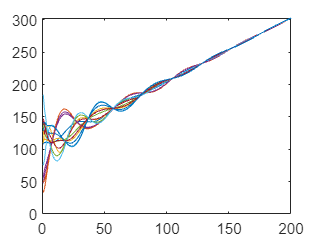


w0=zeros(N,1);
gamma=0.3;
A=zeros(2*N, 2*N);

x_k=x0list;
w_k=w0;
xw_k=[x_k; w_k];
d_ave_scale=sum(d)/N;
d_ave=d_ave_scale*ones(N,1);
D=[d;zeros(N,1)];
%D=[d_ave;zeros(N,1)];
state_save=[];
checkstep=200;
consistent_error=10000;
for n=1:checkstep
    A(1:N, 1:N)=eye(N)-L;
    A(1:N, N+1:2*N)=-eye(N);
    A(N+1:2*N, 1:N)=gamma * L;
    A(N+1:2*N,N+1:2*N)=eye(N);

    xw_k1=A*xw_k+D;
    state_save(:,n)=xw_k1(1:N,:); 

    xw_k=xw_k1;
end

%plot results
nn=1:checkstep;
for p=1:N
    plot(nn,state_save(p,:));
    hold on;
end

## Design of Parameter

Recall that: The corresponding system in matrix form is:


$$\left\lbrack \begin{array}{c}
x\left(k+1\right)\\
w\left(k+1\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
I-L & -I\\
\gamma L & I
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\left(k\right)\\
w\left(k\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
d\\
0
\end{array}\right\rbrack$$


For each element, we need to study the properties of element-wise system matrix: $A=\left\lbrack \begin{array}{cc}
1-\lambda  & -1\\
\gamma \lambda  & 1
\end{array}\right\rbrack$, where $\lambda$ denotes the eigenvalue of the Laplacian matrix and 

 The eigenvlues $z$ of $A$ is the solutions of the equation: 


$${{\left(z-1\right)}^2 +\lambda \left(\gamma +z-1\right)=z}^2 +\left(\lambda -2\right)z+\lambda \gamma -\lambda +1=0$$


To have a fast convergence, we want to minimize $|z|$.

And by analysis, we can find that the boundary is attained by either $\lambda_2$ or $\lambda_N \ldotp$ So to find the best $\gamma$, we implement the following algorithm:

- calculate $\lambda_2 \;$ and $\lambda_N$, given the $L$

- try fixing different $\gamma$, calculating the corresponding $z$ and choose the bigger one among  $\lambda_2 \;$ and $\lambda_N$.

- find the smallest  $|z|$ and its parameter.

[~,D]=eig(L);
lambda_N=D(N,N);
lambda_2=D(2,2);


module_z_list=[];
cnt=0;
%for gamma1=0.01:0.001:0.8
for gamma1=0.01:0.0005:0.8
    cnt=cnt+1;
    const=lambda_2 *gamma1-lambda_2+1;
    syms z
    f2=z*z + (lambda_2 -2) *z + const;
    results=solve(f2==0,z);
    m_z1=abs(results(1));
    m_z2=abs(results(2));

    const=lambda_N *gamma1-lambda_N+1;
    syms z
    fN=z*z + (lambda_N -2) *z + const;
    results=solve(fN==0,z);
    m_z3=abs(results(1));
    m_z4=abs(results(2));

    module_z_list(cnt)=max([m_z1,m_z2,m_z3,m_z4]);

end

min_mz=min(module_z_list);
min_index=find(module_z_list==min_mz);


% 




### Verify 

Find the best parameters by look-up and compare with our results

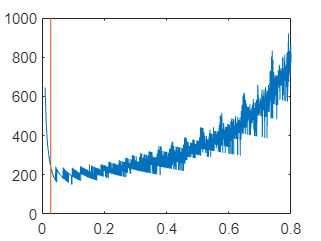


iter_list=[];
cnt=0;
for gamma1=0.01:0.0005:0.8
    cnt=cnt+1;

    iter=1;
    x_k=x0list;
    w_k=w0;
    xw_k=[x_k; w_k];
    d_ave_scale=sum(d)/N;
    d_ave=d_ave_scale*ones(N,1);
    D=[d;zeros(N,1)];
    %D=[d_ave;zeros(N,1)];
    state_save=[];
    checkstep=100;
    consistent_error=10000;

   % while(consistent_error>=0.001/N)
    while(consistent_error>=1/N)
        iter=iter+1;
        A(1:N, 1:N)=eye(N)-L;
        A(1:N, N+1:2*N)=-eye(N);
        A(N+1:2*N, 1:N)=gamma1 * L;
        A(N+1:2*N,N+1:2*N)=eye(N);

        xw_k1=A*xw_k+D;
        state_save(:,n)=xw_k1(1:N,:); 

        xw_k=xw_k1;
        evaluation=xw_k1(1:N,:)-xw_k1(1:N,:)';
        consistent_error=norm(evaluation,2);

    end
    iter_list(cnt)=iter;

end

gamma_set=0.01:0.0005:0.8;
best_gamma=gamma_set(min_index);
figure();
plot(gamma_set, iter_list);
hold on
ylim=[0,1000]; x_index=[best_gamma, best_gamma];
plot(x_index, ylim);